clear all

% Initial
spacecraft.initPosition = [unifrnd(-10,10), unifrnd(-10,10), unifrnd(-10,10)];
spacecraft.initVelocity = [1, 0, 5];
spacecraft.initAcceleration = [0, 0, -100];

spacecraft.position = spacecraft.initPosition;
spacecraft.velocity = spacecraft.initVelocity;
spacecraft.acceleration = spacecraft.initAcceleration;
spacecraft.eulPos = spacecraft.position;
spacecraft.eulVel = spacecraft.velocity;
spacecraft.eulAcc = spacecraft.acceleration;

timeDuration = 100000; % seconds
timeFrame = linspace(0,timeDuration,10);
timeStep = timeFrame(2) - timeFrame(1);

for i = 1:length(timeFrame)
    % Analytical
    analyticalTraj(i,:) = spacecraft.initPosition + spacecraft.initVelocity*timeFrame(i) + 0.5*spacecraft.initAcceleration*timeFrame(i)^2;

    % Euler Integration
    eulTraj(i,:) = spacecraft.eulPos;
    spacecraft.eulAcc = spacecraft.eulAcc;
    spacecraft.eulVel = spacecraft.eulVel + timeStep * spacecraft.eulAcc;
    spacecraft.eulPos = spacecraft.eulPos + timeStep * spacecraft.eulVel;

    % Velocity Verlet Integration
    verletTraj(i,:) = spacecraft.position;
    %verletVel(i,:) = spacecraft.velocity;
    spacecraft.position = spacecraft.position + spacecraft.velocity * timeStep + 0.5 * spacecraft.acceleration * (timeStep ^ 2);
    spacecraft.newAcceleration = spacecraft.acceleration; % Update forces
    spacecraft.velocity = spacecraft.velocity + 0.5 * (spacecraft.acceleration + spacecraft.newAcceleration) * timeStep;
    spacecraft.acceleration = spacecraft.newAcceleration;
end


eulErr = analyticalTraj - eulTraj;
verletErr = analyticalTraj - verletTraj;
for i = 1:size(analyticalTraj,1)
    verlPerf(i) = norm(verletErr(i,:));
    eulPerf(i) = norm(eulErr(i,:));
    analyticalPerf(i) = norm(analyticalTraj(i,:));
    verletVelNorm(i) = norm(verletVel(i,:));
end

% Harmonic Mean
harmonicVel = harmmean(verletVelNorm)

harmonicVel = 50.9895

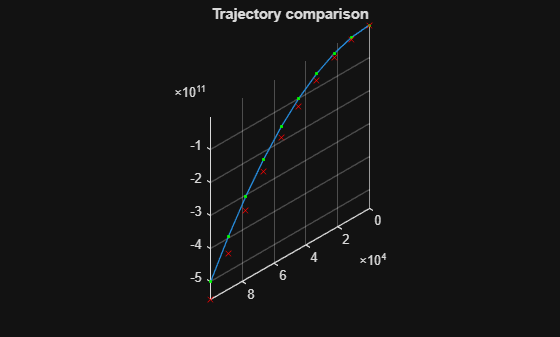

velVect = [spacecraft.initPosition; spacecraft.initPosition + timeDuration * harmonicVel];

figure
hold on
plot3(analyticalTraj(:,1), analyticalTraj(:,2), analyticalTraj(:,3))
plot3(verletTraj(:,1), verletTraj(:,2), verletTraj(:,3), 'g.')
%plot3(velVect(:,1), velVect(:,2), velVect(:,3))
plot3(eulTraj(:,1), eulTraj(:,2), eulTraj(:,3), 'rx')
title('Trajectory comparison')
view([1,1,1])
axis equal
grid on
hold off

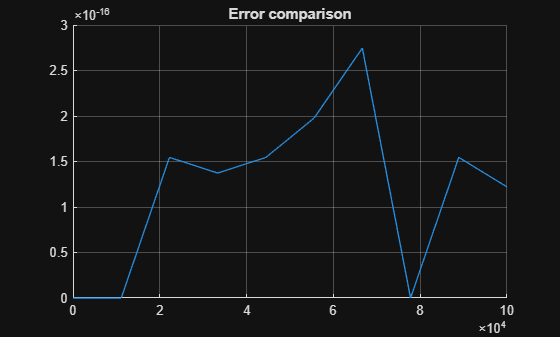


figure
hold on
plot(timeFrame, verlPerf./analyticalPerf)
%plot(timeFrame, eulPerf./analyticalPerf)
title('Error comparison')
grid on
hold off